# STATISTICAL MODELS: LAB 2

## Members:

- Luca Franceschi (u199149)

- Marina Castellano (u188311)

- Paula Ceprián (u198630)

## PROBLEM 1:

File Head_Brothers.xlsx contains measurements of the length and breadth of the heads of pairs of adult brothers in 40 randomly sampled families. We wish to analyze this dataset with techniques that assume multivariate Gaussianity:

### a) Assess whether each of the 4 dimensions of these data is normally distributed. Use α = 0.01 as significance level.

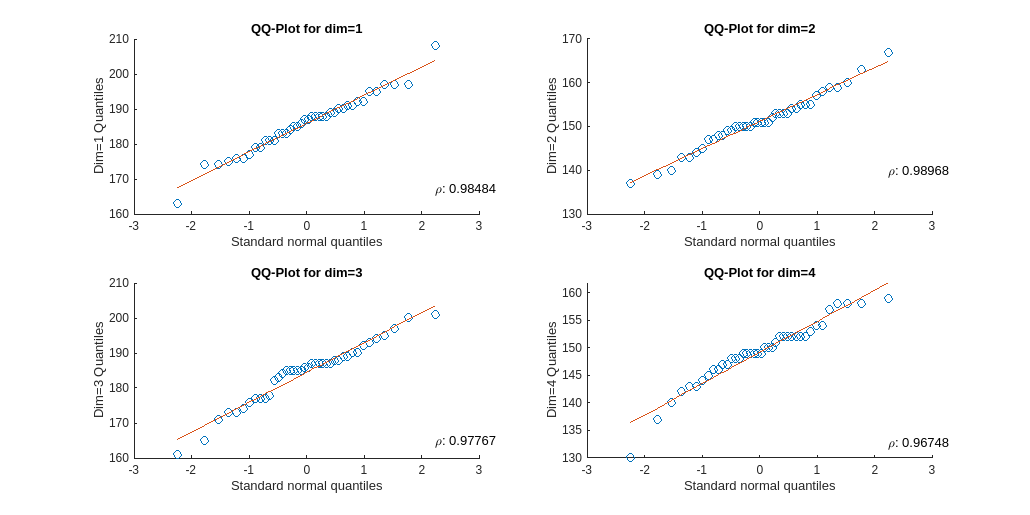

% Importing table
filename = 'lab2/Head_Brothers.xlsx';
file_data_before = 'lab2/Lab_2_Before.xlsx';
file_data_after = 'lab2/Lab_2_After.xlsx';
% check that working directory is ME-2024
raw = readtable(filename);

data = raw{:, 2:5};
alpha = 0.01;

corr = qq_plot(data);

critical_values = readtable('qq_plots_critical.csv');

[n, p] = size(data);
for i=1:p
    if corr(i) > retrieve_qq_critical(critical_values, n, alpha)
        disp(['We fail to reject that dimension ' num2str(i) ' follows a normal distribution.'])
    else
        disp(['We can reject that dimension ' num2str(i) ' follows a normal distribution.'])
    end
end

We fail to reject that dimension 1 follows a normal distribution.
We fail to reject that dimension 2 follows a normal distribution.
We fail to reject that dimension 3 follows a normal distribution.
We fail to reject that dimension 4 follows a normal distribution.


As we can see on the qq-plots, we **fail to reject that all dimensions of these data are likely normally distributed**, as the plots are quite straight lines and the correlation value between the ordered data and the quantiles is bigger than the critical threshold (which we have looked in the table* for n=40 and α = 0.01).

**Table 4.2 p. 182 from Johnson, R.A. & Wichern, D.W. Applied Multivariate Statistical Analysis (5th Ed.)*

### b) Assess whether each pair of dimensions is normally distributed.

As we have seen in the qq-plots, as all dimensions are univariately likely to be normal, we can continue with **bivariate normality**. For that, we use **chi-square plots**:

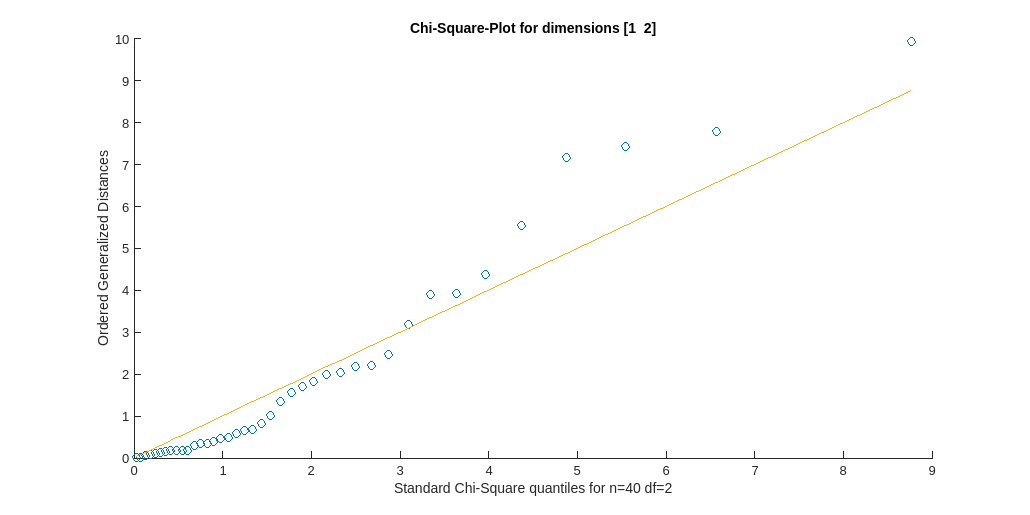

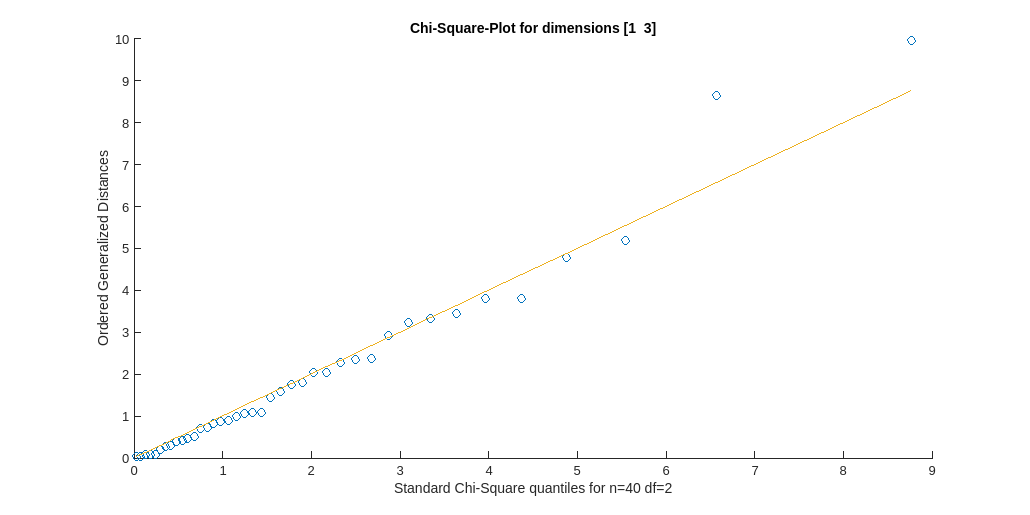

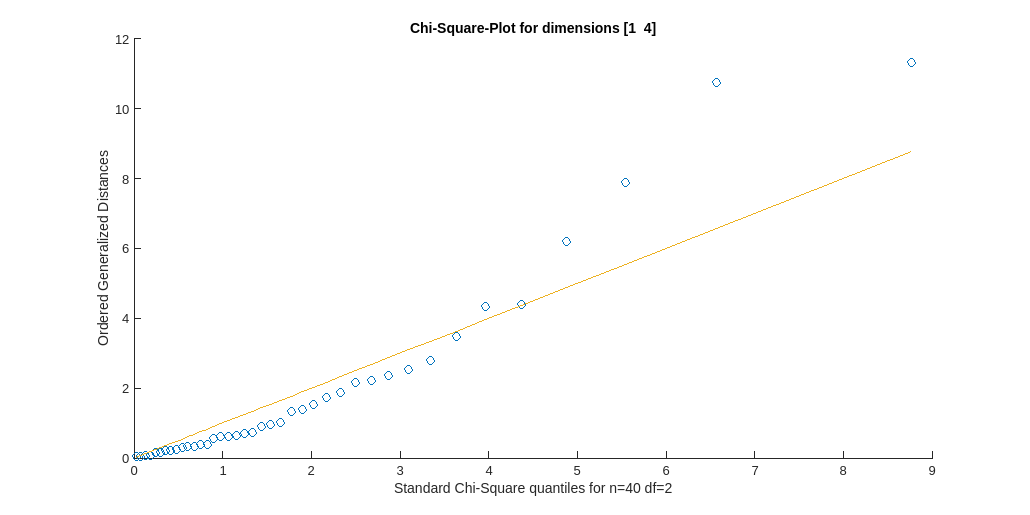

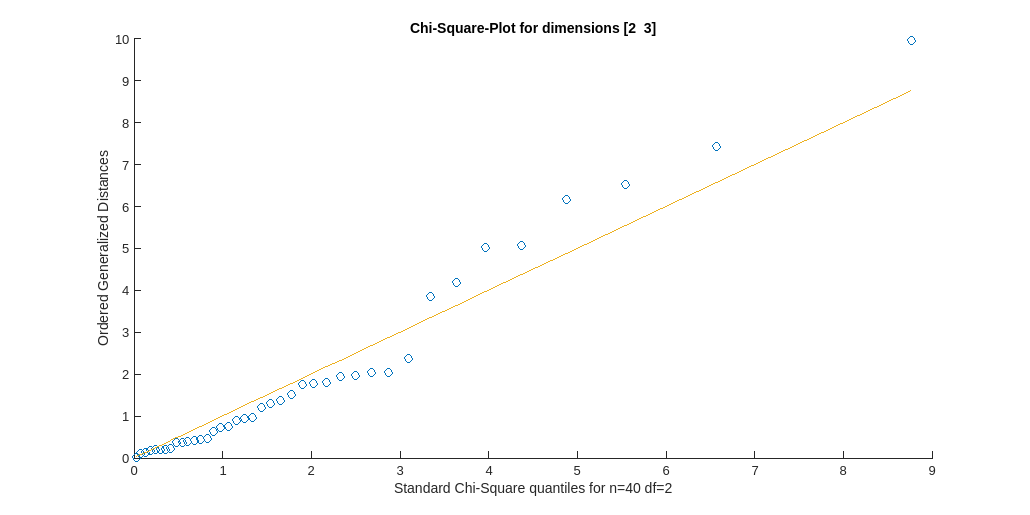

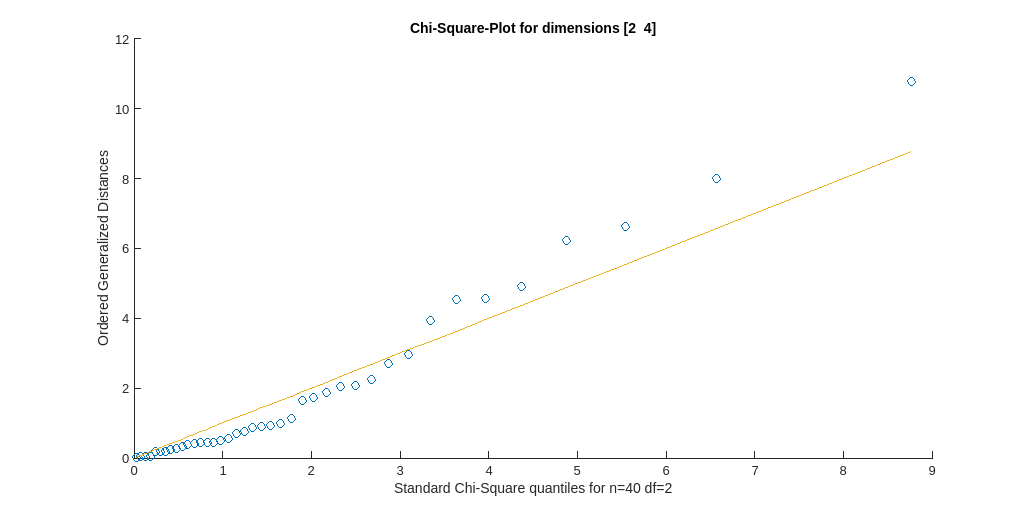

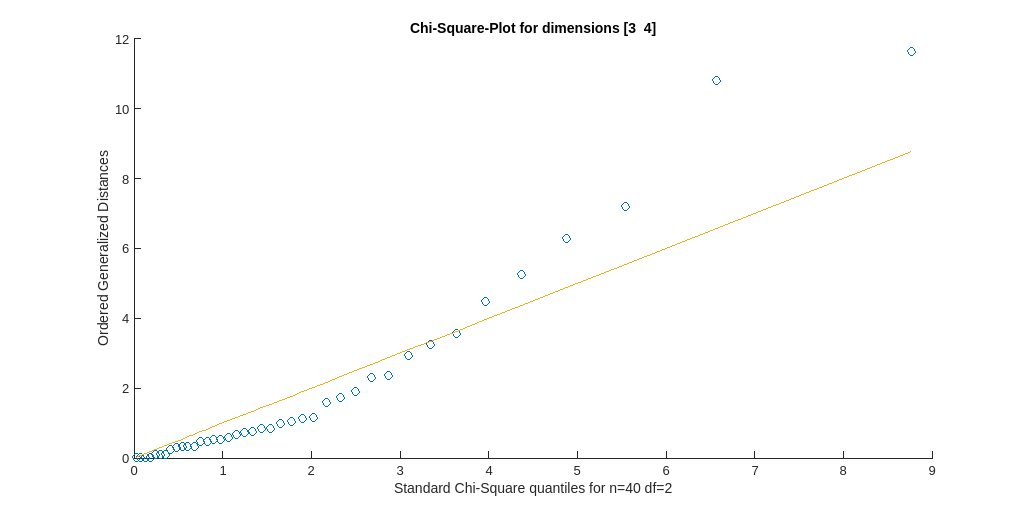

for i=1:p
    for j=i+1:p
        chi_square_plot(data, 2, alpha, [i j]);
    end
end

We consider a small sample size if n ≤ (30 + 10*extra_dimension). Hence, as we have 1 extra dimension (because we have 2 dimensions), n is small is n ≤ 30+10 = 40. Concretely, our sample is n=40, we can consider our sample small. Then, if our sample is small, we do not have enought points to have a very significant result. The chi-squared plots seem to be straight lines with slope 1 and passing through the origin, but neither of them is a perfect plot. That is why we conclude that it is not enough informative to be able to reject it. Therefore, we **fail to reject bi-variate normallity distribution.**

### c) Compute a chi-squared plot for all 4 dimensions considered together.

As we have seen in (b) that bi-variate normality has been failed to reject, we can continue to check all the 4 dimensions together, and therefore check multivariate normality, also with a chi-squared plot:

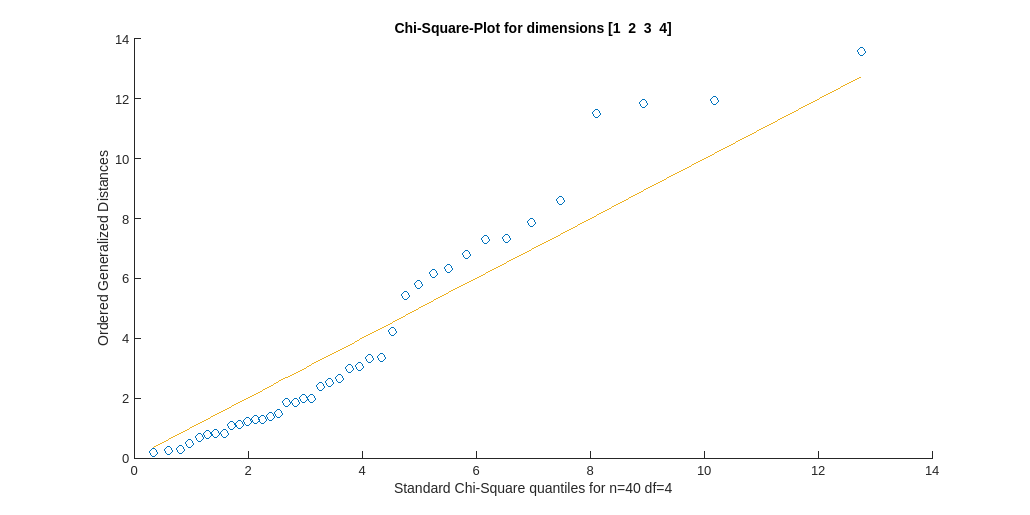

chi_square_plot(data, 4, alpha, 1:4)

Similarly to the explanation of (b), the chi-squared plot seem to be straight line with slope 1 and passing through the origin, but is not a perfect plot. Therefore, we **fail to reject multivariate normallity distribution.**

### d) Identify possible outliers. If one or more outliers are found, concisely discuss what shall be done with it/them.

Here we will show a scatter plot of each dimensions separately, to see the overall distribution of each individual variable separately. It is only for a matter of seeing how variables are distributed.

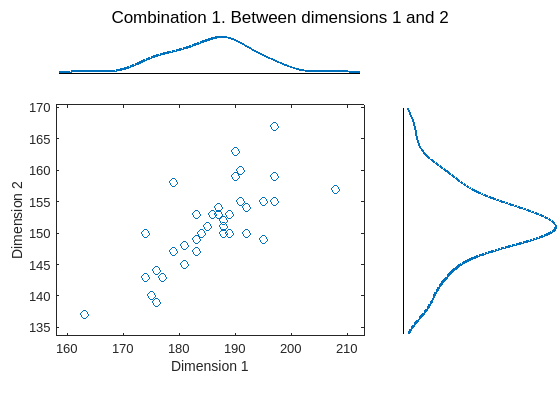

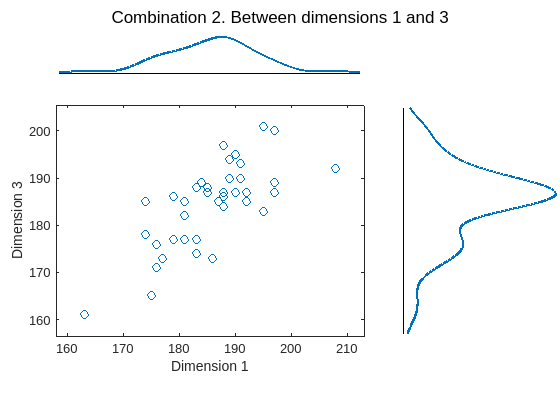

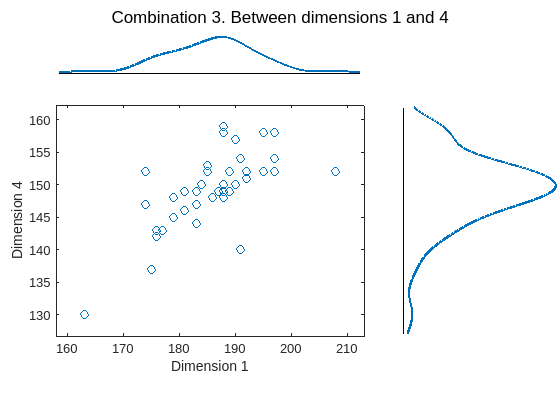

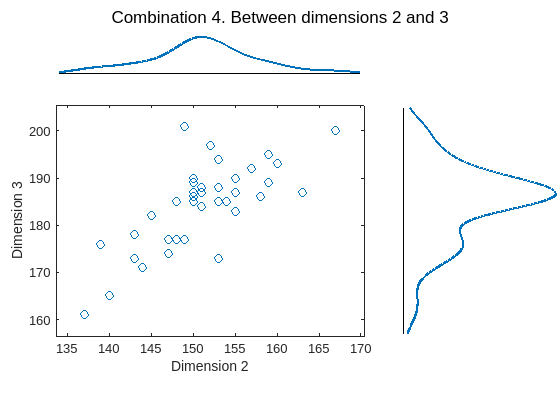

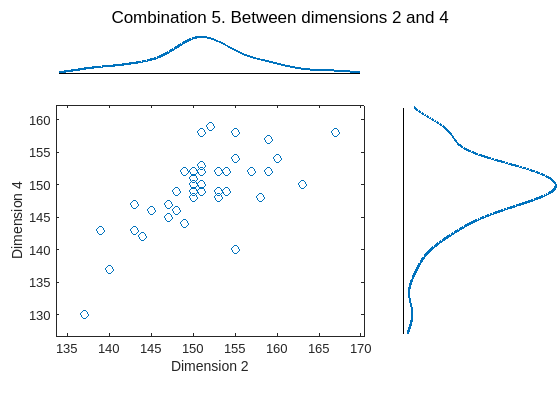

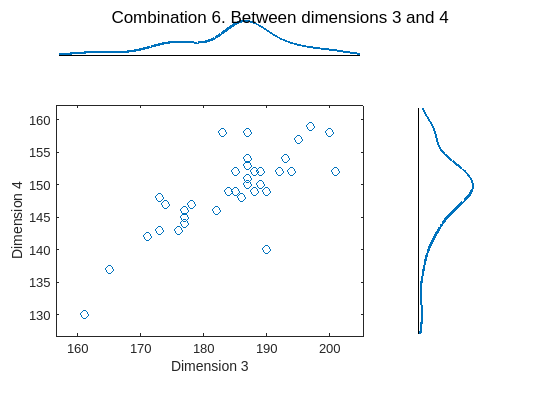

% Steps
% Make dot plot for each variable
k = 1;
for i=1:p
    for j=i+1:p
        marginalscatter(data, i, j, ['Dimension ' num2str(i)], ['Dimension ' num2str(j)]);
        sgtitle(['Combination ' num2str(k) '. Between dimensions ' num2str(i) ' and ' num2str(j)]);
        k = k+1;
    end
end

Here we are identifying the outliers, checking if they are inside of the confidence interval given by the normal distribution. We standarize first the data, and the commpare it to a normal distribution:

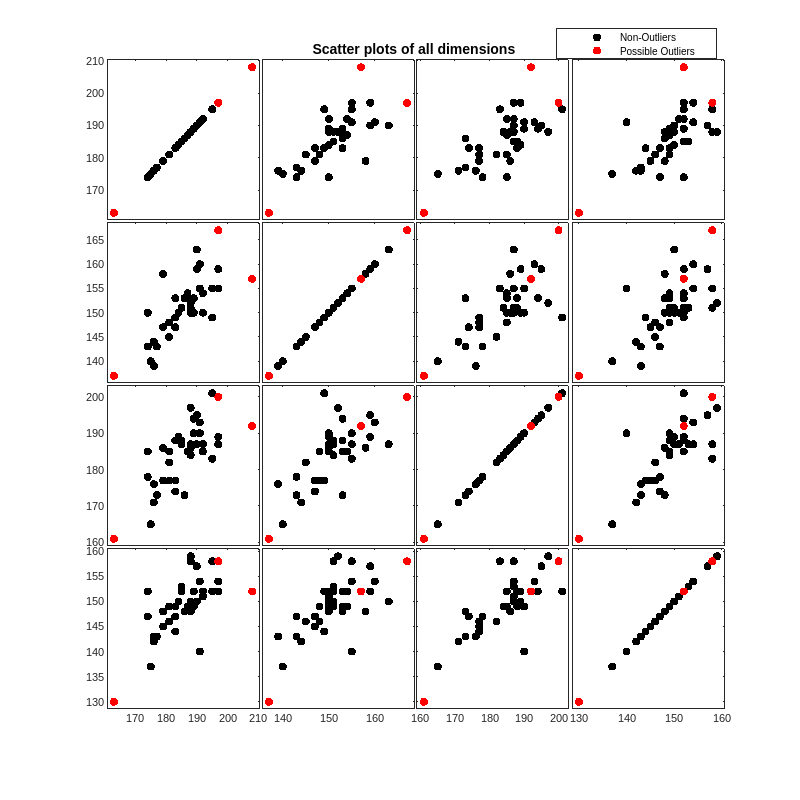

% Calculate and analyze standardized values (relative to size of dataset)
possible_outliers_logical_std = max(abs(standardize(data)) > abs(norminv(1-alpha)), [], 2);

% Make scatter plots for each pair of variables
figure('Position', [100 100 1000 1000]);
gplotmatrix(data, data, possible_outliers_logical_std, ['k', 'r']);
h = findobj('Tag','legend');
set(h(1), 'String', {'Non-Outliers', 'Possible Outliers'}, 'Position', [0.7155 0.9282 0.1600, 0.0331]);
title('Scatter plots of all dimensions');

Finally, we compute how many outliers do we have checking if the mahalanobis distances are bigger than the chi-squared inverse cummulative distribution, with n degrees of freedom and confidence of 1-α.

% Examine high values in chi-squared plot
possible_outliers_logical_chi = generalized_squared_distances(data) > chi2inv(1-alpha, n);
sum(possible_outliers_logical_chi);

### e) Based on all the above information, indicate whether you would find it acceptable to test this dataset using statistical techniques that assume the data following an (approximately) multivariate normal distribution. Make a clear and concise justification of your answer.

We could not find any significant reason (with confidence level 0.99) that the data is not multivariate normal, so assuming that it is should be a solid bet. Therefore, as with all the plots we have failed to reject MV normality, there is** no need to do it statiscally.**

## PROBLEM 2:

A group of 100 subjects is administered a new treatment and we are asked to analyze whether it produces a significant effect. To this end, we are provided with two random samples:

- File Lab_2_Before.xlsx contains measurements for the overall physical and mental health (two values per subject, in a continuous scale from 0=poor health to 100=excellent health) before the treatment.

- File Lab_2_After.xlsx contains measurements for the overall physical and mental health (two values per subject, in a continuous scale from 0=poor health to 100=excellent health) after the treatment.

### a) State the null and alternative hypotheses for this problem.

- Null Hypothesis (Ho): There is no significant difference in the overall physical and mental health before and after a new treatment ($H_0$: $\delta_B ={\;\delta }_A$).

- Alternative Hypothesis (Ha): There is significant difference in the overall physical and mental health before and after a new treatment ($H_A$: $\delta_0 \not= {\;\delta }_1$)

, where $\delta$is the difference of the means before and the mean after.

### b) Indicate what method would you use to answer the research questions of this Problem.

As the samples are not independent, that is, they are repeated measures, because we have two different set of observations that correspond to the same people: before the treatment and after the treatment. Hence, will use Comparison of 2 Multivariate Means with MANOVA where we have repeated measures. For that, we need to use the data doing the difference between the subjects before the treatment and the subjects after the treatment. In this way, we will only have 1 population of the difference, and not 2, and thefore we will do a **Paired **$T^2$** test**.

### c) State the assumptions required by your method and assess whether the provided data fulfils all of them. In case assumptions are not met, go back to (b) and choose a different method, repeating (c) until all assumptions are fulfilled.

In order to test the hypotheses, there are some assumptions that should be taken into account:

- Every observation should be i.i.d (independent and identically distributed) from the rest of the observations in the same group. That is, the subjects that received the treatment mus the i.i.d between them.

- The observations of the difference in health before and after the treatments should follow a Normal distribution.

- (Sphericity (sometimes called circularity). For our data to fullfil that the variances of the differences for all pairs of repeated measures be equal.)

For the first assumption, as we cannot check whether the samples are i.i.d between them, we will assert that they are i.i.d. Therefore, **first assumption is fulfilled**.

To check whether the second assumption, that is, that the observations follow a normal distribution, we should first check if each dimension follows uni-variate normality with qq-plots, but, as we have n large (n=100), there is no need of checking them, as we can assume uni-variate normality for both Var1 and Var2, and go to the next step, that is checking if the dimensions together follow bi-variate normality with chi-squared plot:

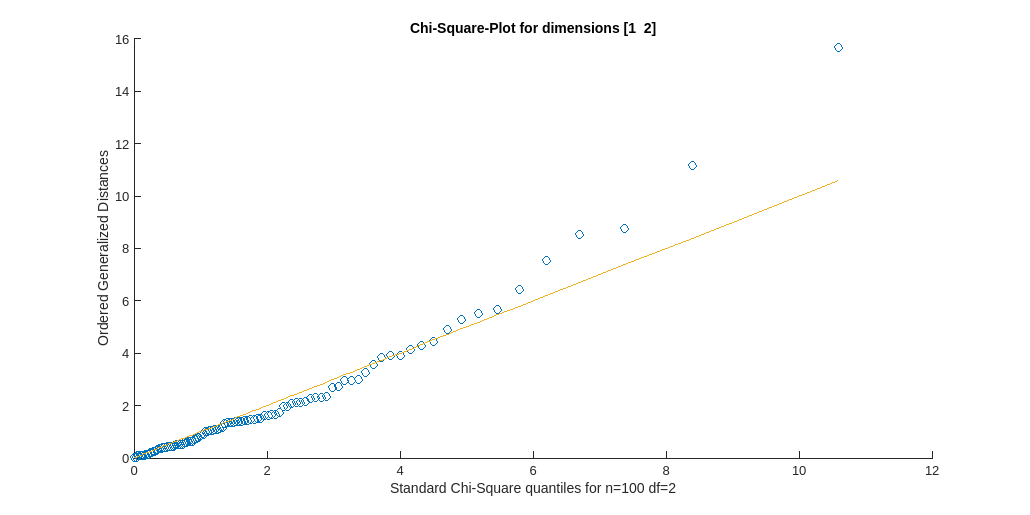

% no need to do qq-plots this since n>40 n is large (explained above)

alpha=0.05;
data_before = readtable(file_data_before, 'ReadVariableNames', false);
data_after = readtable(file_data_after, 'ReadVariableNames', false);
data_diff = data_after - data_before;
data_diff = data_diff{:,:};
[n, p] = size(data_diff);
chi_square_plot(data_diff, 2, alpha, 1:2)

As we can see, the chi-squared plot follows a straight line (with slope = 1), and also passes thorugh the origin (0, 0), we can not reject that this variables follow a normal distribution. Furthermore, in the plot, visually we have noticed we may have some outliers. For that, we have checked if that was the case. After checking taht, we have seen that there are no outliers. Therefore, **second assumption is fulfilled**.

Finally, to check the third assumption, that is Sphericity, the variances of the differences for all pairs of repeated measures should be equal.  But, for only 2 dimensions (Var1 and Var2), we cannot reach a sphere, as it has 3 dimensions. Hence, we need to check circularity, but if we assume spehericity the circularity is always fulfilled. Therefore, **third assumption is fulfilled**.

### d) Apply the method selected in (b) to answer the research question, at significance level α = 0.05. Indicate your conclusions.

% Paired T^2 test
X_bar = mean(data_diff, 1);
S = cov(data_diff);
t2_hat = n * X_bar / S * X_bar'

t2_hat = 40.7109

t2_crit = (n-1) * p / (n-p) * finv(1-alpha, p, n-p)

t2_crit = 6.2415

### e) Construct a 95% confidence region for the (population) mean difference in health measurements before and after treatment. Analyze whether the resulting region confirms your conclusion in (d).

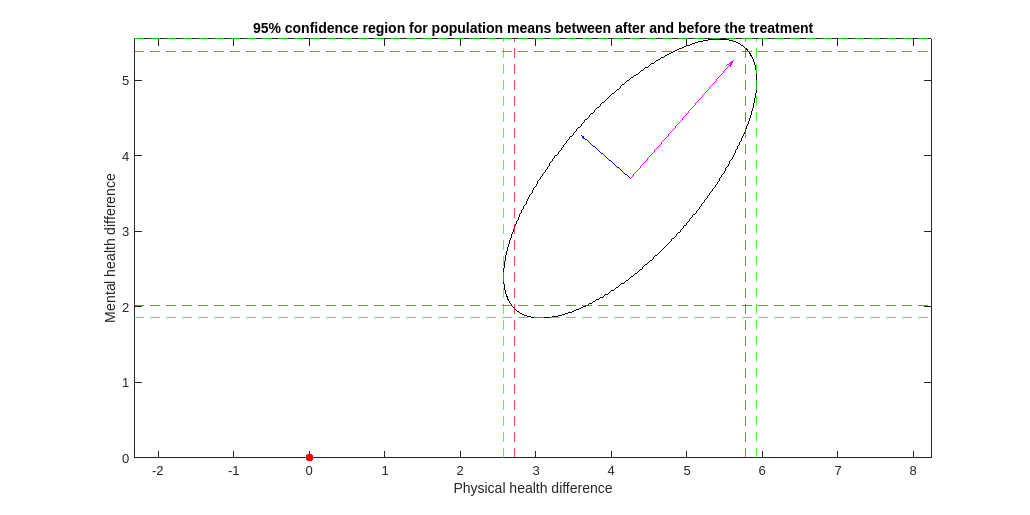

drawCI(data_diff, alpha)
hold on;
title('95% confidence region for population means between after and before the treatment');
xlabel('Physical health difference');
ylabel('Mental health difference');
hold off;

As we see in this plot, the X-axis is the physical health difference and Y-axis the mental health difference. The red point corresponds to the sample mean of the difference of the data after the treatment and before the treatment. As we see, the sample mean is in (0, 0), and does not lie inside the confidence region with confidence of 95%. Therefore, we were correct and we reject the Null Hypothesis. 

# FUNCTIONS

function ci = confInterval(pop, alpha)
    [n, p] = size(pop);
    c = sqrt((n-1)*p / (n-p) * finv(1-alpha, p, n-p));
    s_diag = diag(cov(pop)); % vector containing the diagonal only OF COVARIANCE
    x_bar = mean(pop);
    ci = [x_bar' - c*sqrt(s_diag/n), x_bar' + c*sqrt(s_diag/n)];
end

function bfci = bonferroniConfInterval(pop, alpha)
    [n, p] = size(pop);
    c = tinv(1-alpha/(2*p), n-1);
    s_diag = diag(cov(pop)); % vector containing the diagonal only
    x_bar = mean(pop);
    bfci = [x_bar' - c*sqrt(s_diag/n), x_bar' + c*sqrt(s_diag/n)];
end

function axis = getEllipsisAxis(pop, alpha)
    [n, p] = size(pop);
    c = sqrt((n-1)*p / (n-p) * finv(1-alpha, p, n-p));

    [eVec, eVal] = eig(cov(pop));
    eVal = diag(eVal);

    axis = c * sqrt(eVal/n)' .* eVec;
end

function drawCI(pop, alpha)
    % First we draw the ellipsis 
    center = mean(pop);
    ellipsis_axis = getEllipsisAxis(pop, alpha);

    t = -pi:0.01:pi;
    circle = [cos(t)', sin(t)'];
    ellipsis = center + circle * ellipsis_axis';

    plot(ellipsis(:,1), ellipsis(:,2), 'k');
    hold on;

    % Then we plot the axis of the ellipsis
    quiver(center(1), center(2), ellipsis_axis(1,1), ellipsis_axis(2,1), 'b');
    quiver(center(1), center(2), ellipsis_axis(1,2), ellipsis_axis(2,2), 'm');

    % Now we draw the confidence intervals (Hotelling's)
    ci = confInterval(pop, alpha);
    xline(ci(1,1), '--g');
    xline(ci(1,2), '--g');
    yline(ci(2,1), '--g');
    yline(ci(2,2), '--g');

    % Finally we draw the Bonferroni-corrected confidence intervals
    bfci = bonferroniConfInterval(pop, alpha);
    xline(bfci(1,1), '--r');
    xline(bfci(1,2), '--r');
    yline(bfci(2,1), '--r');
    yline(bfci(2,2), '--r');

    scatter(0, 0, 'or', 'filled');

    hold off;
    axis equal;
end

function corr = retrieve_qq_critical(table, n, alpha)
    cols = [NaN 0.01 0.05 0.1]; % table is formatted this way to make it easier
    col = ismember(cols, alpha);
    if ~any(col)
        error 'Invalid confidence level. Allowed ones are {0.01, 0.05, 0.1}'
    end

    if any(ismember(table{:, 'n'}, n))
        % disp('Entry exists');
        corr = table{table{:, 'n'} == n, :}(col);
    elseif n > 300
        disp('Too large n. Will approximate to n=300');
        corr = table{table{:, 'n'} == 300, :}(col);
    else
        % disp('Entry does not exist, performing linear interpolation');
        lowerBound = table{table{:, 'n'} < n, :}(end,:);
        upperBound = table{table{:, 'n'} > n, :}(1,:);
        corr = linspace(lowerBound(col), upperBound(col), upperBound(1)-lowerBound(1));
        corr = corr(n-lowerBound(1)+1);
    end
end

function corr = correlation_coeff(data)
    % Get shape of the data
    n = size(data, 1);
    
    % Order all dimensions by ascending value
    ordered_data = sort(data);
    
    % Get standard normal quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = norminv(p);

    % Compute correlation coefficient
    num = q * (ordered_data - mean(ordered_data, 1));
    denom1 = diag((ordered_data - mean(ordered_data, 1))' * (ordered_data - mean(ordered_data, 1)))';
    denom2 = q * q';
    
    corr = num ./ sqrt(denom1 .* denom2);
end

function corr = qq_plot(data)
    % Get shape of the data
    [n, dims] = size(data);
    
    % Order all dimensions by ascending value
    ordered_data = sort(data);
    
    % Get standard normal quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = norminv(p);
    
    figure
    set(gcf,'position',[0,0,2000,1000]);

    corr = correlation_coeff(data);
    
    % Draw the corresponding QQ-Plots with regression line
    for i=1:dims
        % Create subplot
        subplot(ceil(sqrt(dims)),floor(sqrt(dims)), i);

        % Scatter plot and regression line in each axis
        scatter(q, ordered_data(:, i));
        hold on;
        b = [ones(n, 1) q']\ordered_data(:,i);
        ycalc = [ones(n, 1) q']*b;
        plot(q, ycalc);

        % Display correlation coefficient too
        y = (ordered_data(end,i)-ordered_data(1,i))*0.1 + ordered_data(1,i);
        text(q(end), y, ['\rho: ' num2str(corr(i))]);
        hold off;

        % Set title and labels for each axis
        title(['QQ-Plot for dim=' num2str(i)]);
        xlabel('Standard normal quantiles');
        ylabel(['Dim=' num2str(i) ' Quantiles']);
    end
end


function h = marginalscatter(data, dim1, dim2, xlabel, ylabel)
    figure;
    h = scatterhist(data(:,dim1), data(:,dim2), 'kernel', 'on', 'Location', 'NorthEast', 'Direction', 'out');
    
    h(2).Position = h(2).Position .* [1 1 1 0.4];
    h(3).Position = h(3).Position .* [1 1 0.4 1];
    h(1).Position(2) = h(1).Position(2) + 0.1;
    h(2).Position(2) = h(2).Position(2) + 0.1;
    h(3).Position(2) = h(3).Position(2) + 0.1;

    h(1).YAxisLocation = 'left';
    h(1).XAxisLocation = 'bottom';
    h(1).XLabel.String = xlabel;
    h(1).YLabel.String = ylabel;
end

function z = standardize(data)
    s = cov(data);
    z = (data - mean(data)) ./ sqrt(diag(s))';
end


function d2 = generalized_squared_distances(data)
    x_bar = mean(data);
    S = cov(data);
    d2 = diag((data - x_bar) / S * (data - x_bar)'); % / equivalent to * inv(S)
end

function chi_square_plot(data, df, alpha, dims)
    % the p parameter is an integer in the range(2,n) that considers how
    % many variables are analyzed jointly
    % Get shape of the data
    data = data(:, dims);
    n = size(data,1);
    
    % Order the squared distances
    d2 = sort(generalized_squared_distances(data));
    
    % Get standard chi-square quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = chi2inv(p, df);

    possible_outliers_logical = d2 > chi2inv(1-alpha, n);

    figure('Position',[0,0,2000,1000]);

    % Scatter plot and ideal slope
    scatter(q, d2');
    hold on;
    scatter(q(possible_outliers_logical), d2(possible_outliers_logical)', 'or');
    title(['Chi-Square-Plot for dimensions [' num2str(dims) ']']);
    ylabel('Ordered Generalized Distances');
    xlabel(['Standard Chi-Square quantiles for n=' num2str(n) ' df=' num2str(df)]);
    plot(q, q); % page 184 it should have a slope of 1 for comparison
    hold off;
end